load("data.mat")


## Q1

fprintf('Mean of ret')

Mean of ret

meanRet = mean(ret)

meanRet = 0.0010

fprintf('Var of ret')

Var of ret

varRet = var(ret)

varRet = 7.8077e-04

fprintf('Autocorrelation of ret')

Autocorrelation of ret

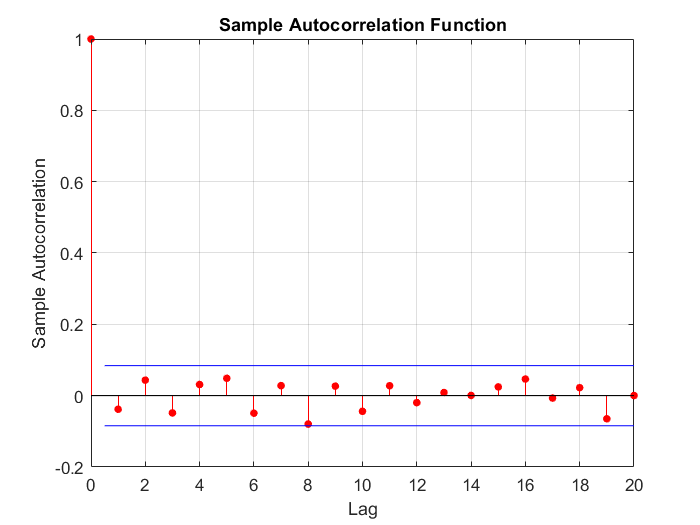

autocorr(ret,NumLags=20)

## Q2


% See function LB defined at the bottom

fprintf('p-value of LB test')

p-value of LB test

LB(ret,20)

ans = 0.6386


% Since p-value > 0.05. Do not reject null hypothesis of no
% autocorrelation.


## Q3

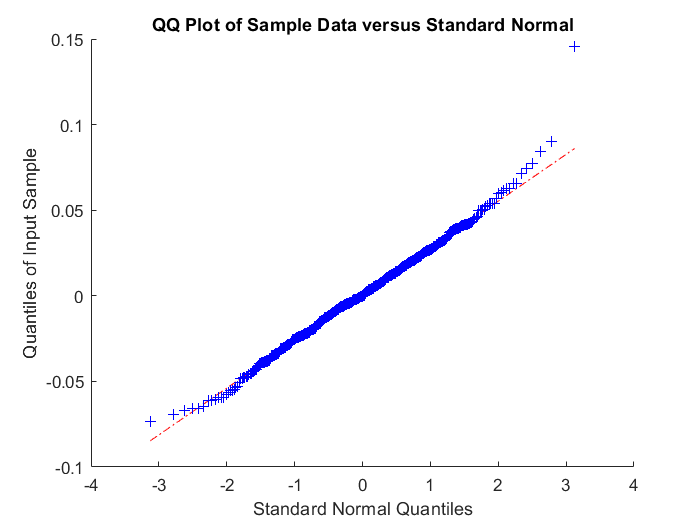

% Compares distribution of ret to a normal distribution
qqplot(ret)

## Q4

fprintf('p-value of LB test for absolute values of return')

p-value of LB test for absolute values of return

LB(abs(ret),20)

ans = 1.1016e-07


% Since p-value < 0.05. Reject null hypothesis


## Q5

Tco2 = size(co2,1);

ranktest1 = 0;
for (i = 1:(Tco2-1)) 
    for (j = (i+1):Tco2)
    ranktest1 = ranktest1 + 1*(co2(j)>co2(i));
    end
end

meanNullRT = (Tco2*(Tco2-1))/4;
varNullRT = Tco2*(Tco2-1)*(2*Tco2+5)/72;

zRT1 = (ranktest1 - meanNullRT)/sqrt(varNullRT);

%% Two sided test

fprintf('H0: co2 has no linear trend')

H0: co2 has no linear trend

fprintf('H1: co2 has a linear trend')

H1: co2 has a linear trend

fprintf('p-value of two-sided rank test')

p-value of two-sided rank test

pvalueRT1 = 2*(1-normcdf(abs(zRT1)))

pvalueRT1 = 0


% Since p-value < 0.05. Reject null hypothesis of no linear trend

%% One sided test

fprintf('H0: co2 has a positive linear trend')

H0: co2 has a positive linear trend

fprintf('H1: co2 does not have a positive linear trend')

H1: co2 does not have a positive linear trend

fprintf('p-value of one-sided rank test')

p-value of one-sided rank test

pvalueRT1 = 1-normcdf(zRT1)

pvalueRT1 = 0


% Since p-value < 0.05. Reject null hypothesis of no positive linear trend



## Q6


% Stores output: b = betas of regression
% bint = interval for betas at 95% significance 
% resid = residuals of regression

[b,bint,resid] = regress(co2,[ones(Tco2, 1) (1:Tco2)']);


ranktest2 = 0;
for (i = 1:(Tco2-1)) 
    for (j = (i+1):Tco2)
    ranktest2 = ranktest2 + 1*(resid(j)>resid(i));
    end
end

% Same values for mean and sd under null as before

zRT2 = (ranktest2 - meanNullRT)/sqrt(varNullRT);

fprintf('p-value of two-sided rank test')

p-value of two-sided rank test

pvalueRT2 = 2*(1-normcdf(abs(zRT2)))

pvalueRT2 = 0.8668


% Since p-value > 0.05. Do not reject null hypothesis of no linear trend
% for residuals



## Q7

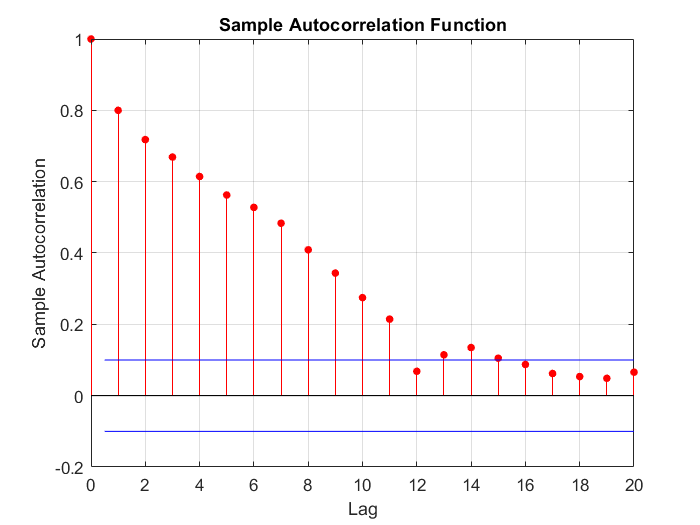

autocorr(co2)


LB(co2,20)

ans = 0


% co2 does not appear to be realization of iid process


## LB FUNCTION BELOW

function p = LB(x, h)
   T = size(x,1);
   autocorrH = autocorr(x,NumLags=h);
   autocorrH = autocorrH(2:end,1);
   qLB = sum(T*(T+2)*(autocorrH).^2./((T-(1:h))'));
   p = 1 - chi2cdf(qLB,h);
end
